IDX = 2911

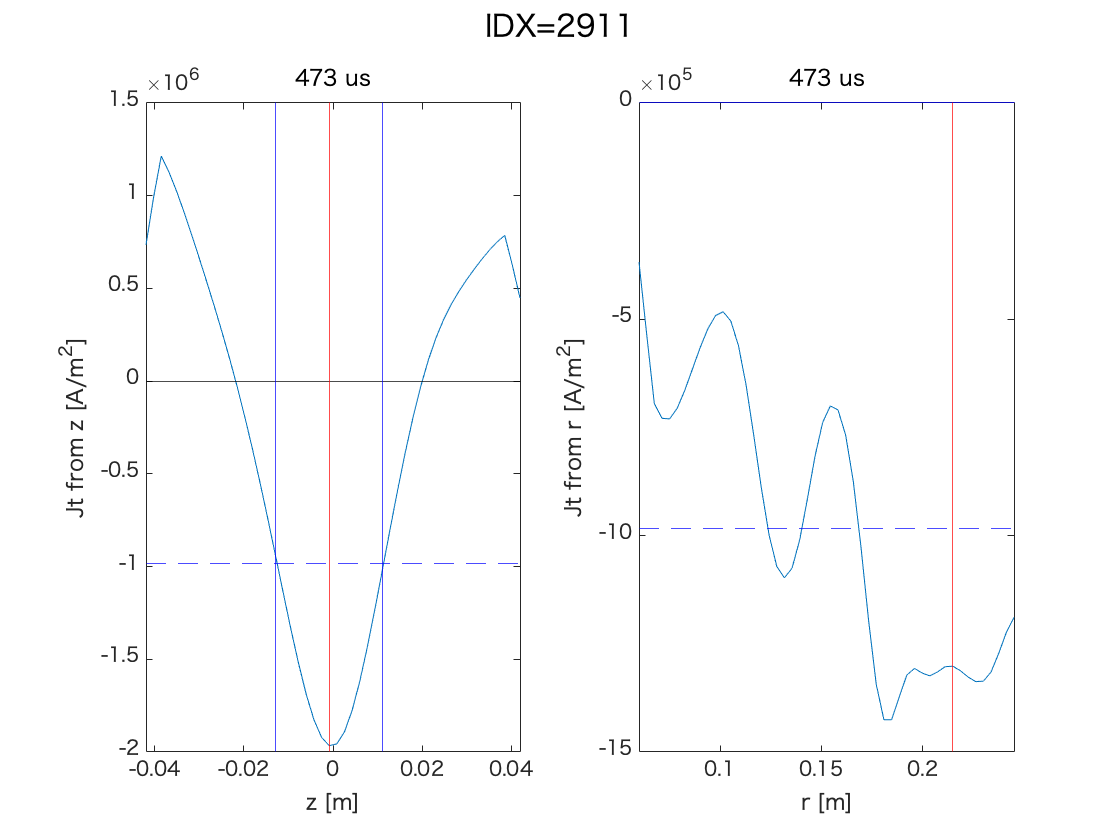

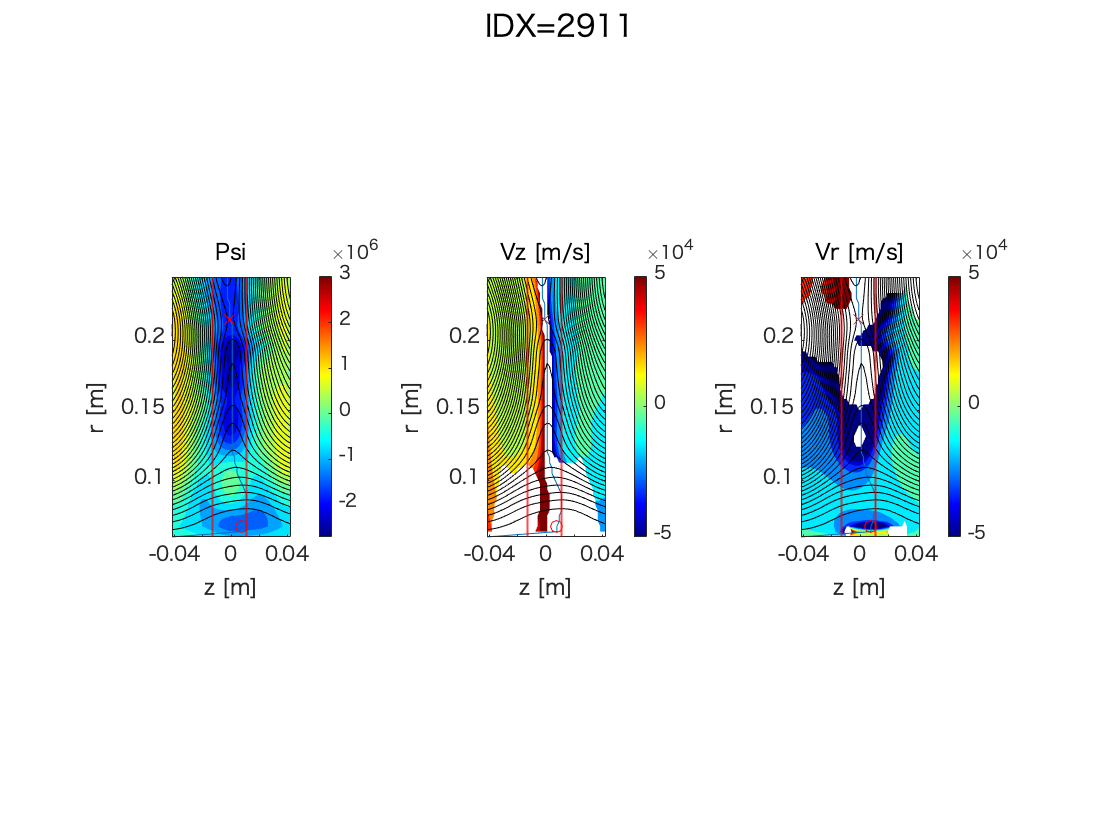

IDX = 2912

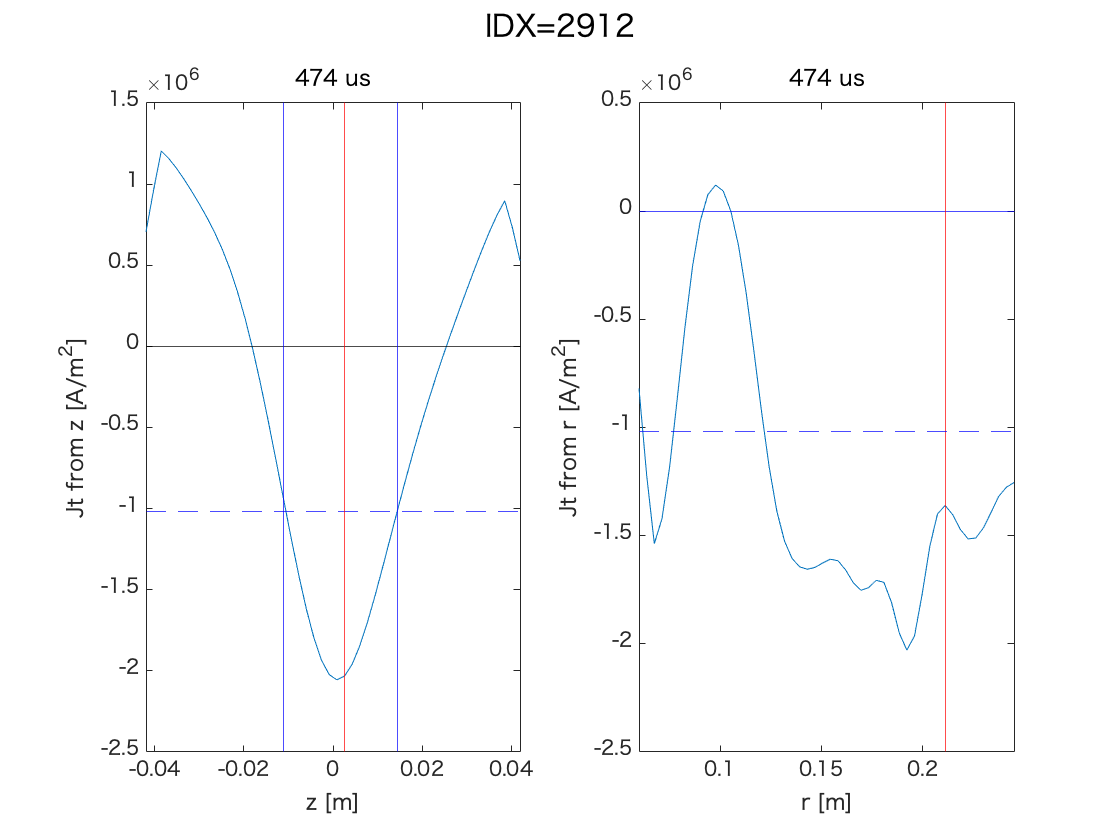

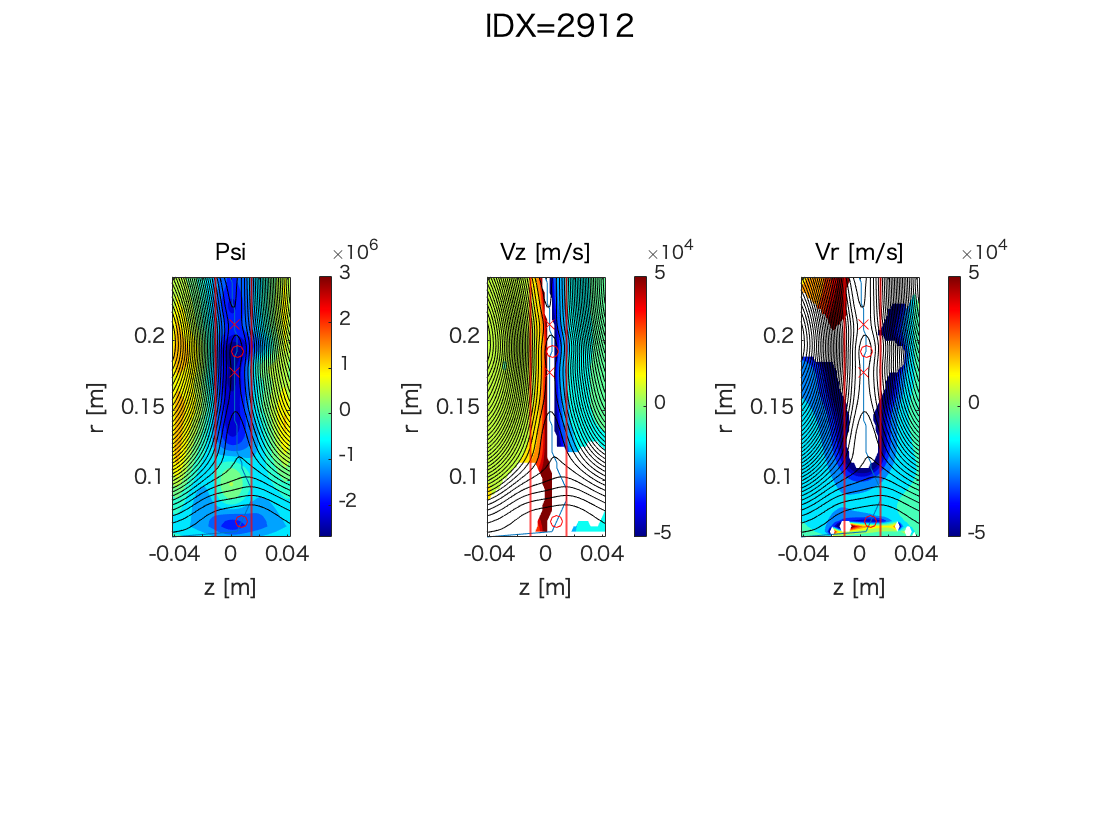

IDX = 2913

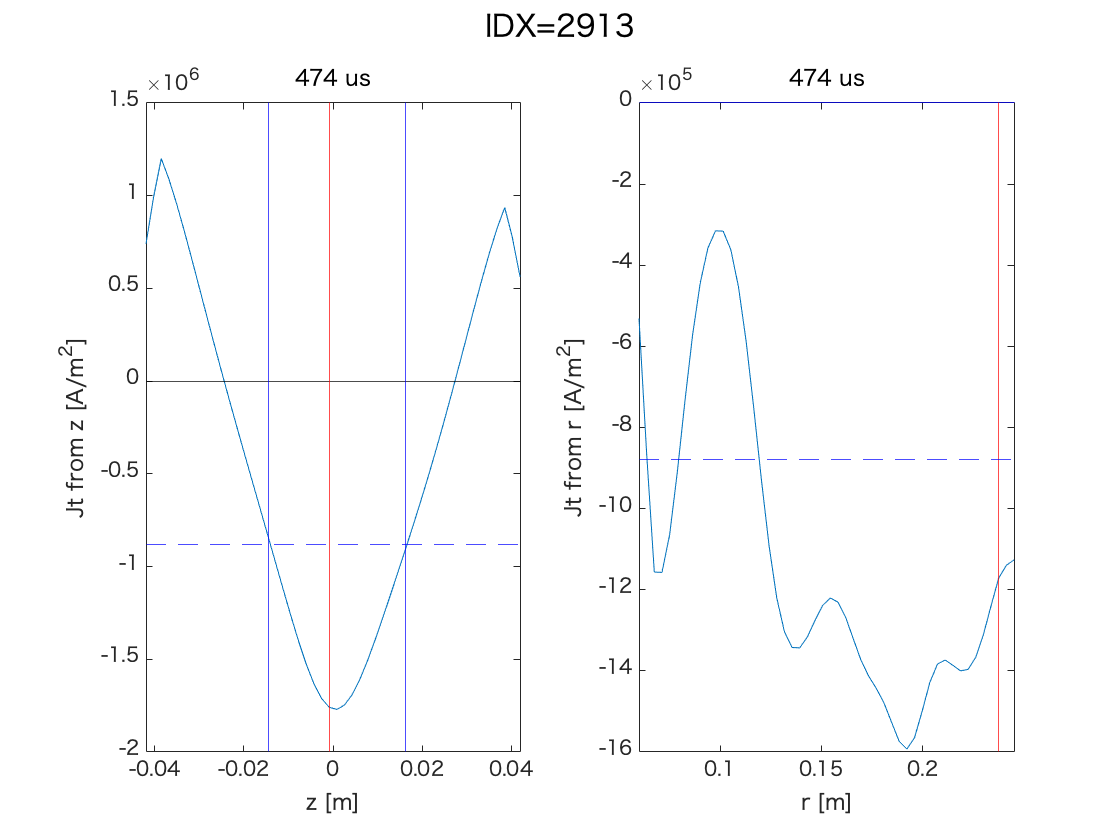

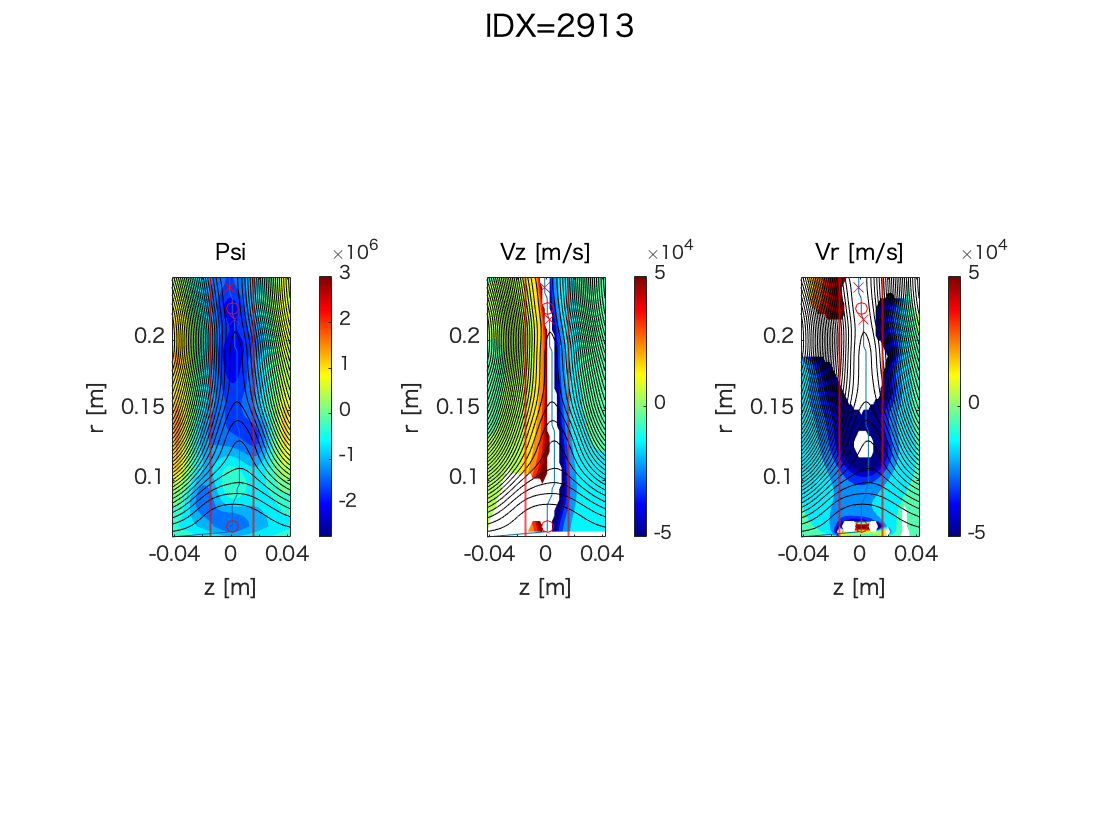

IDX = 2925

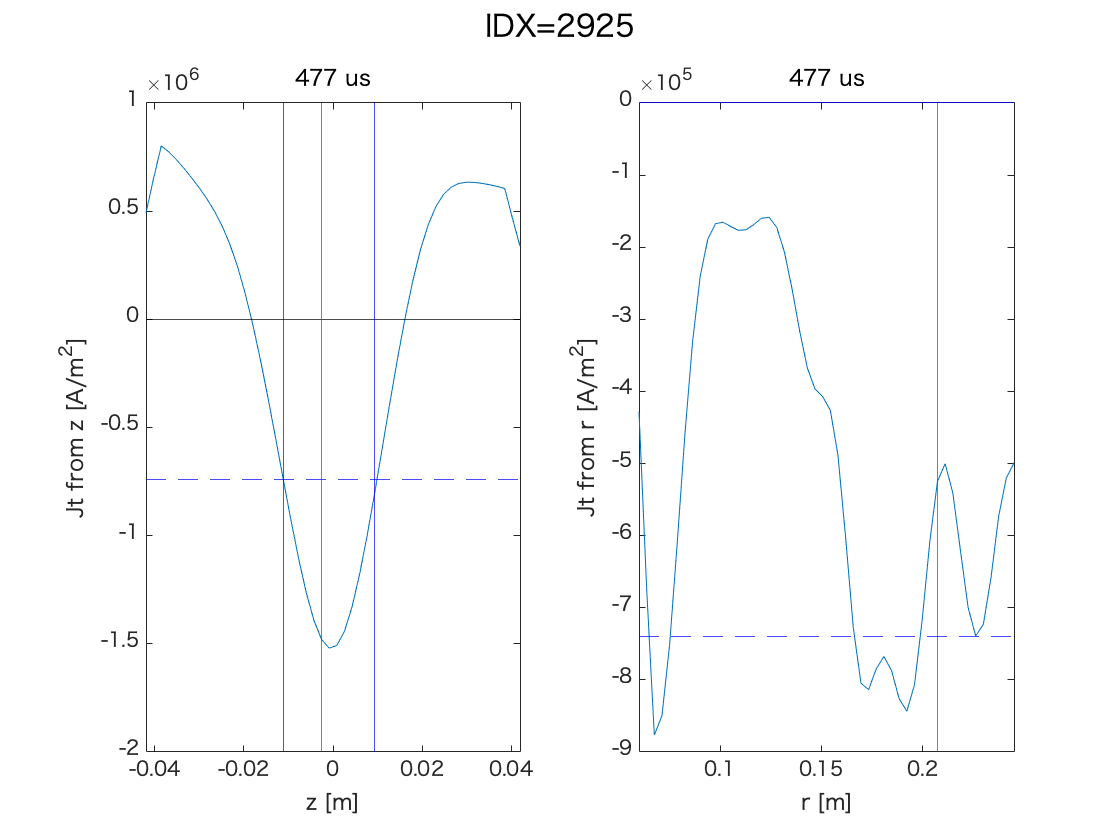

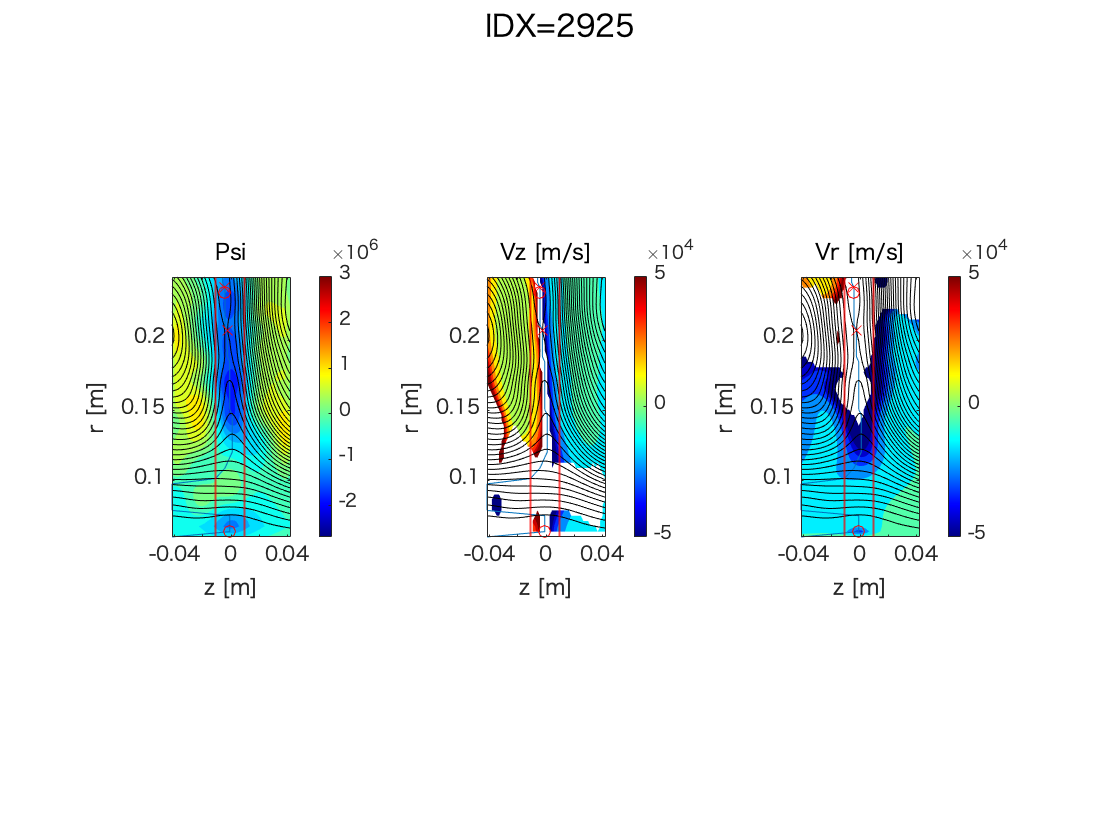

IDX = 2926

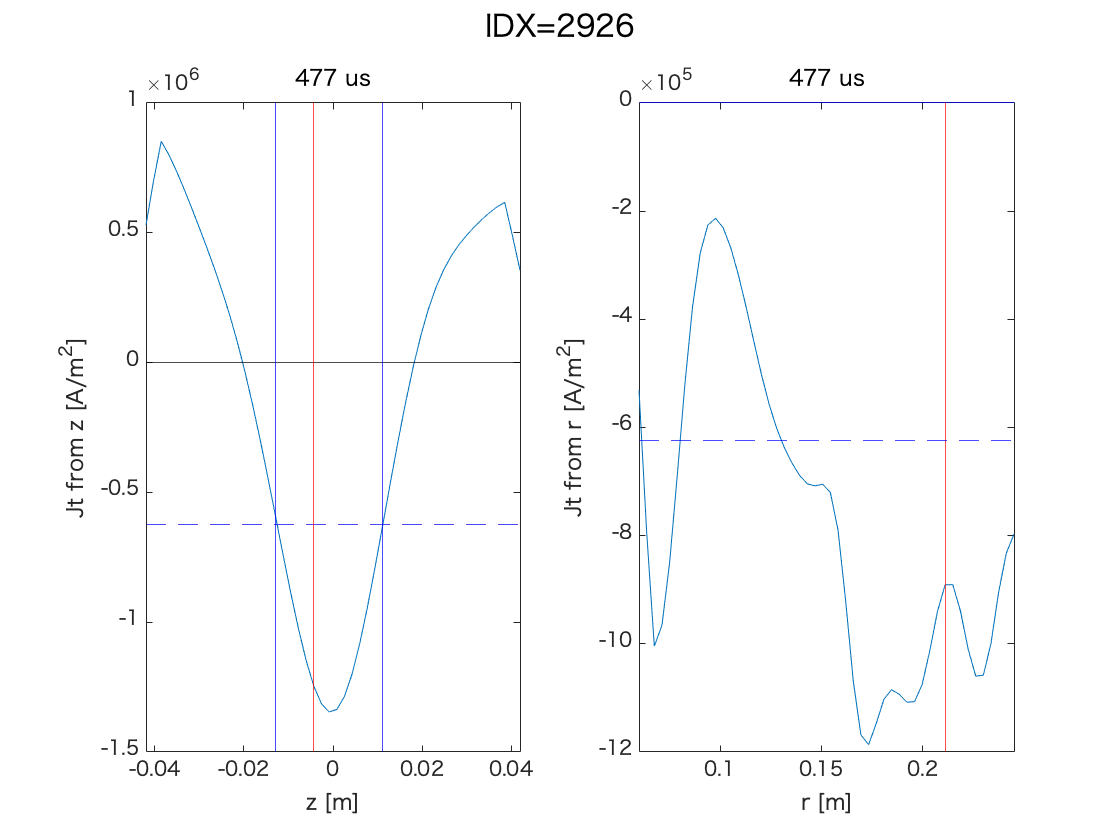

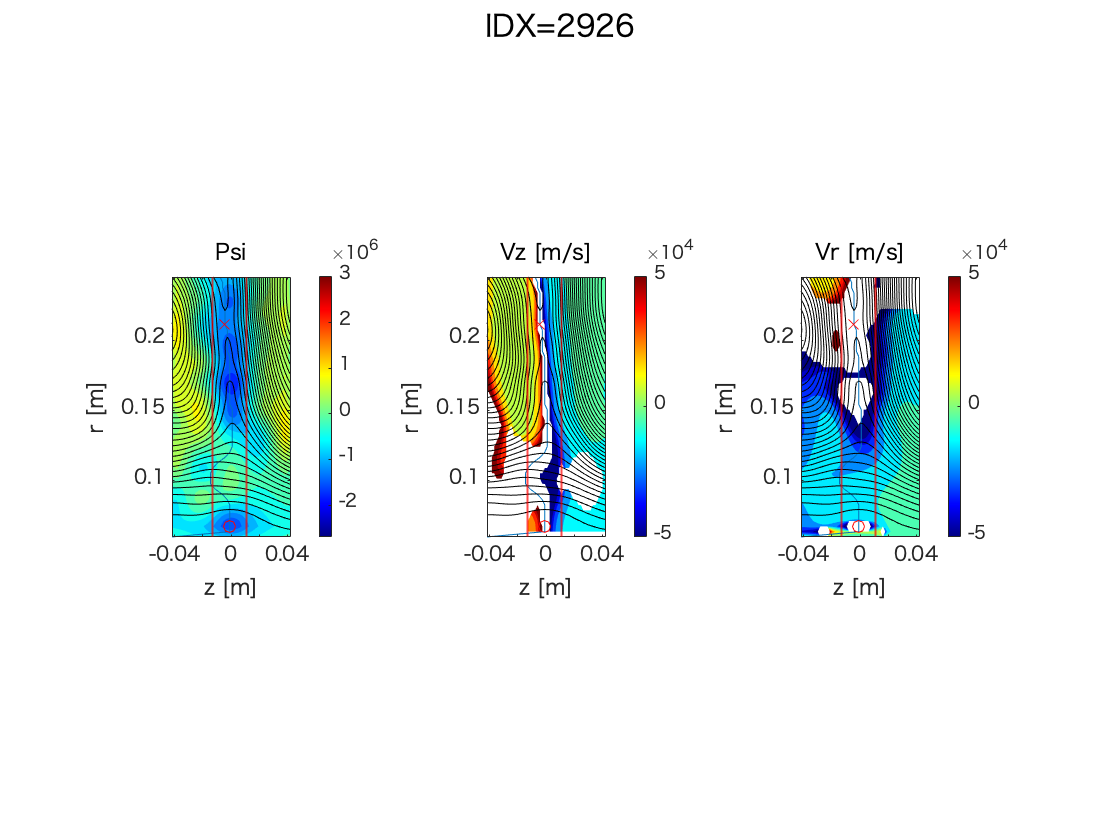

IDX = 2927

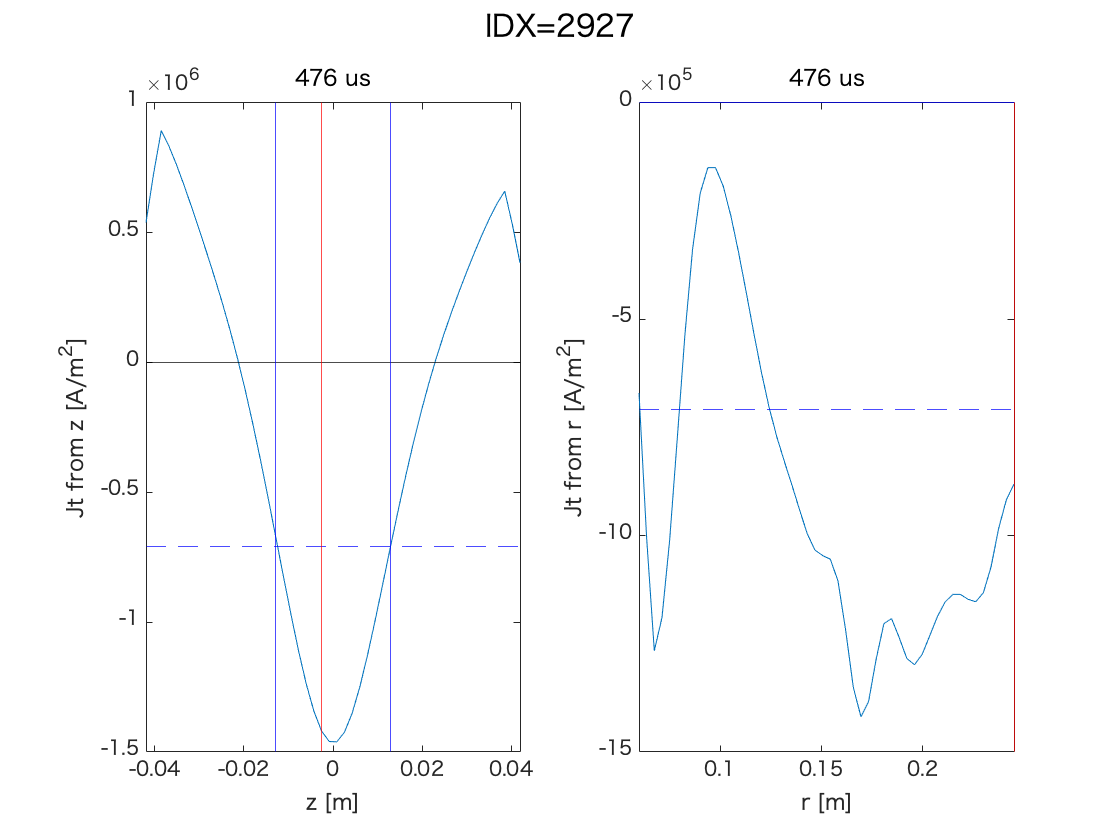

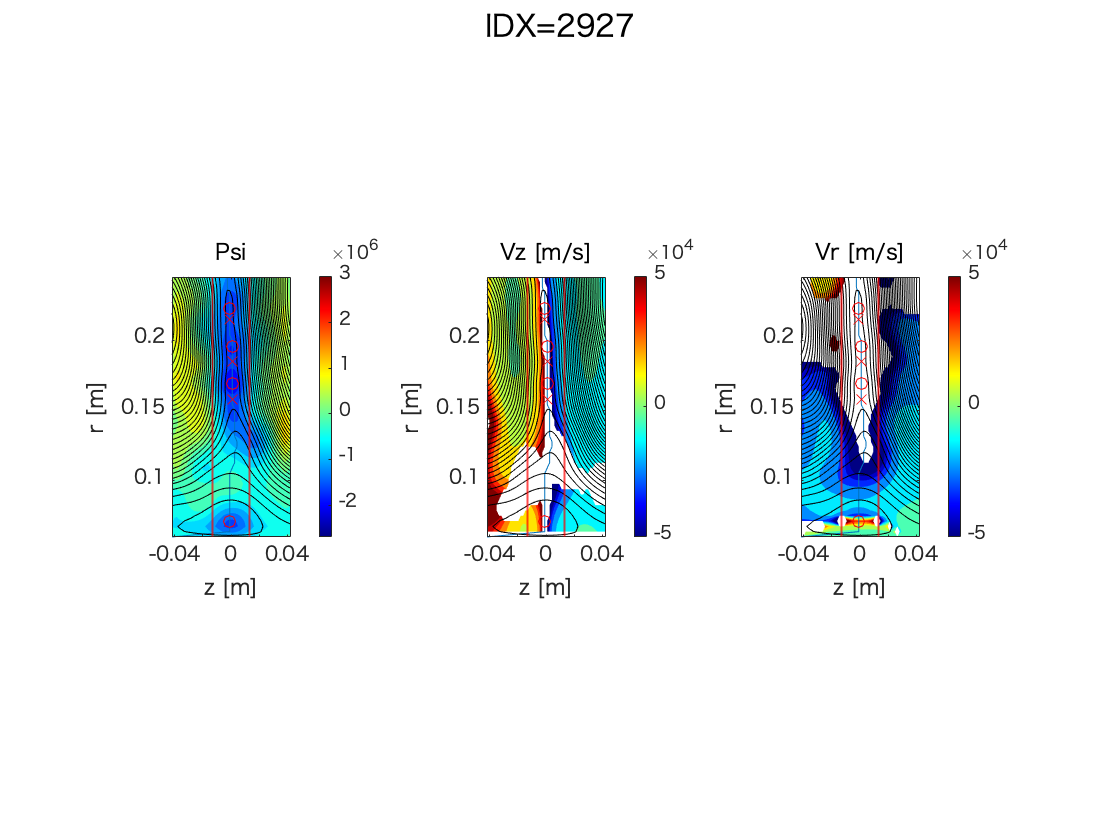

IDX = 2931

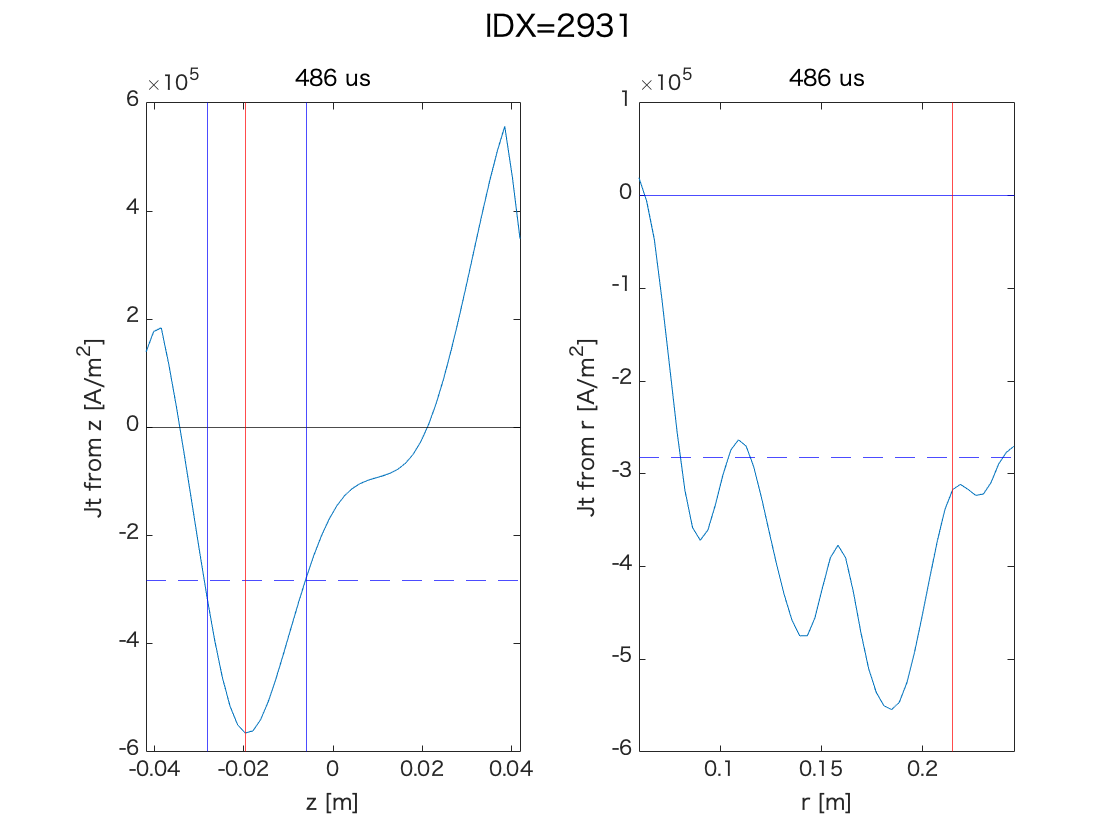

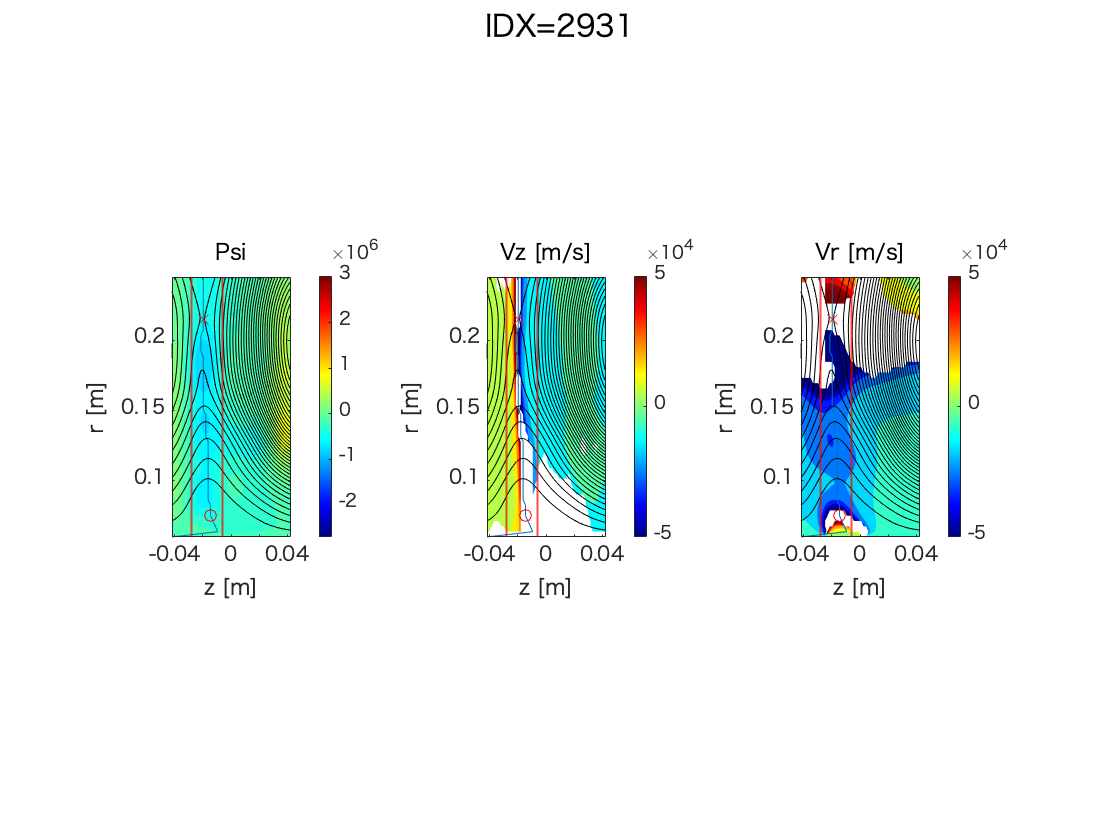

IDX = 2933

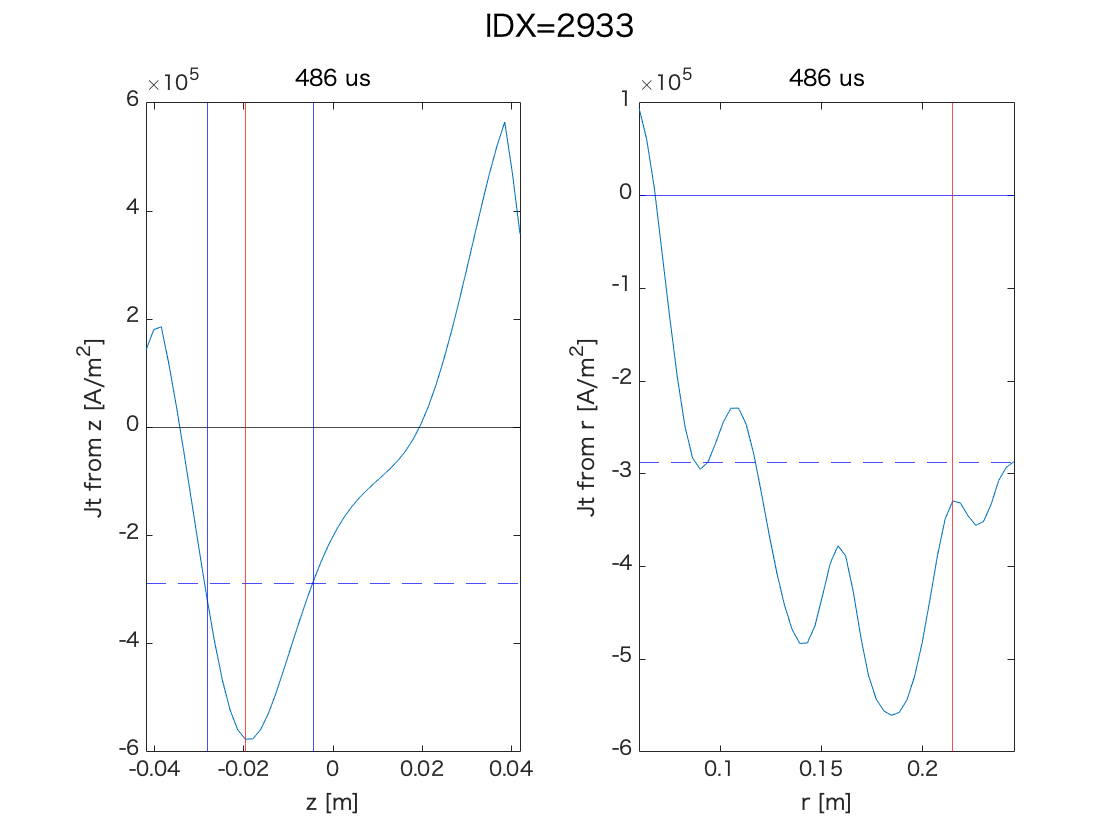

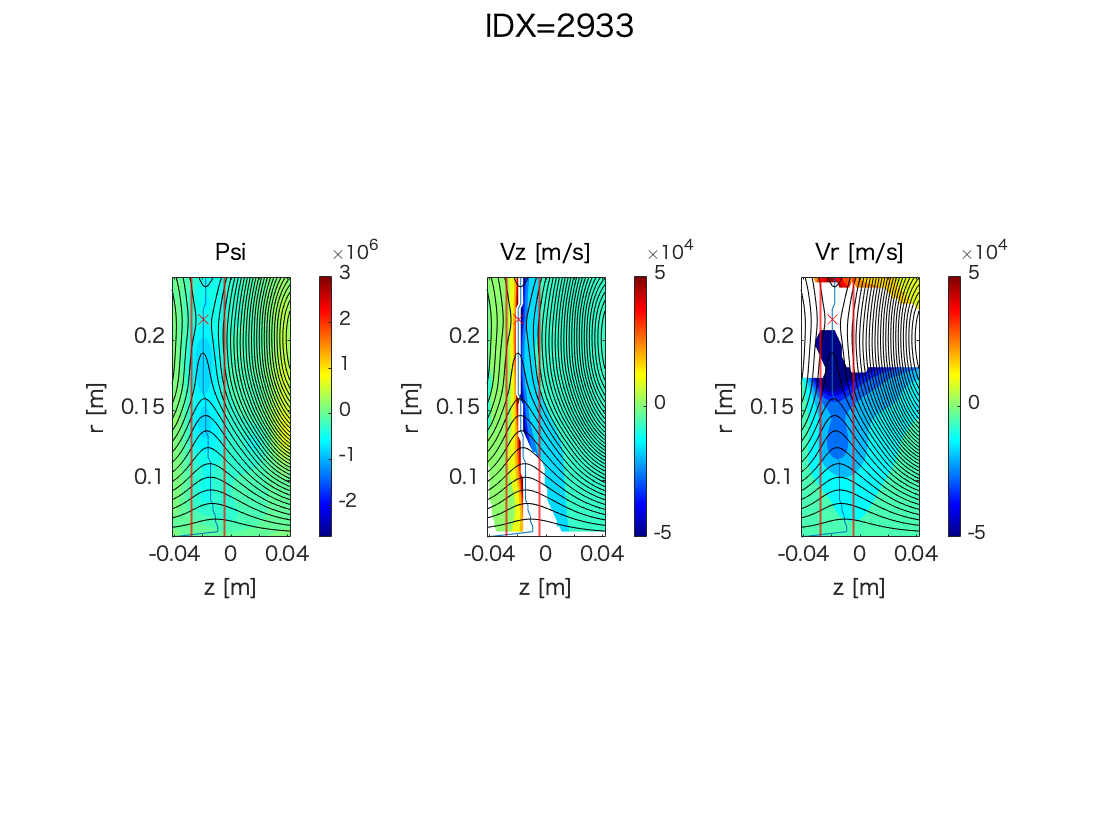

IDX = 2947

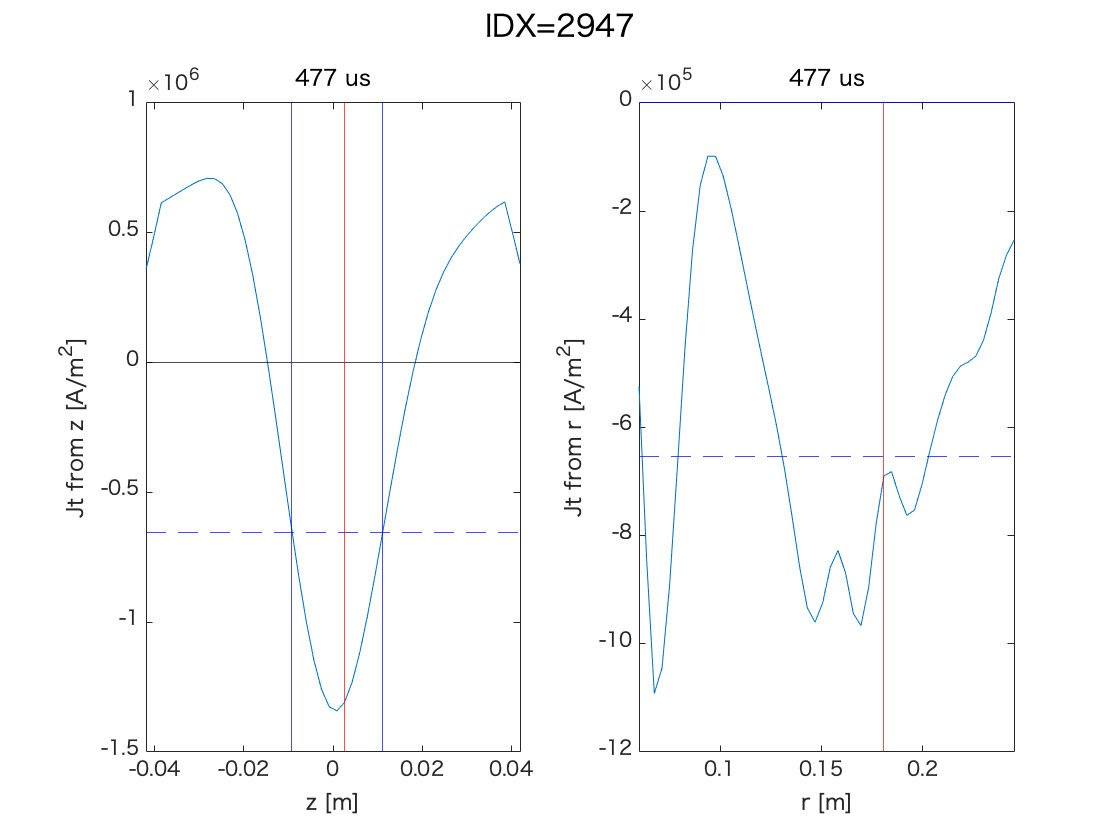

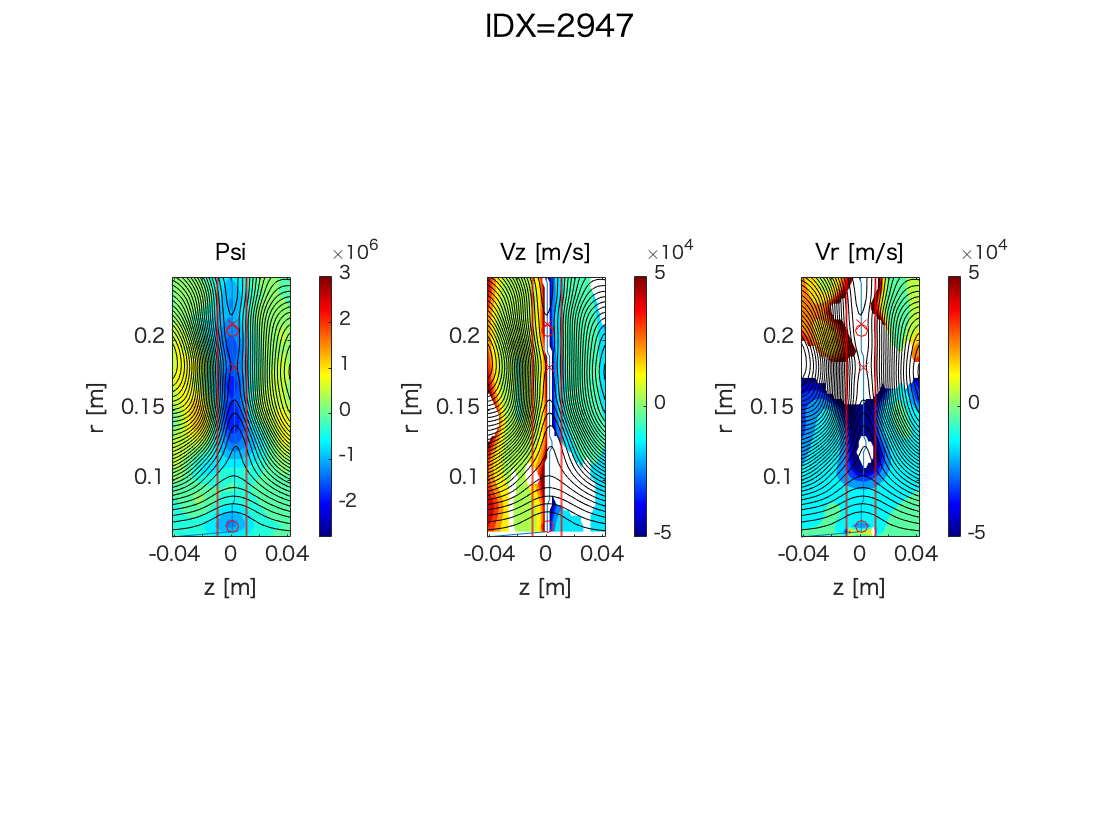

IDX = 2948

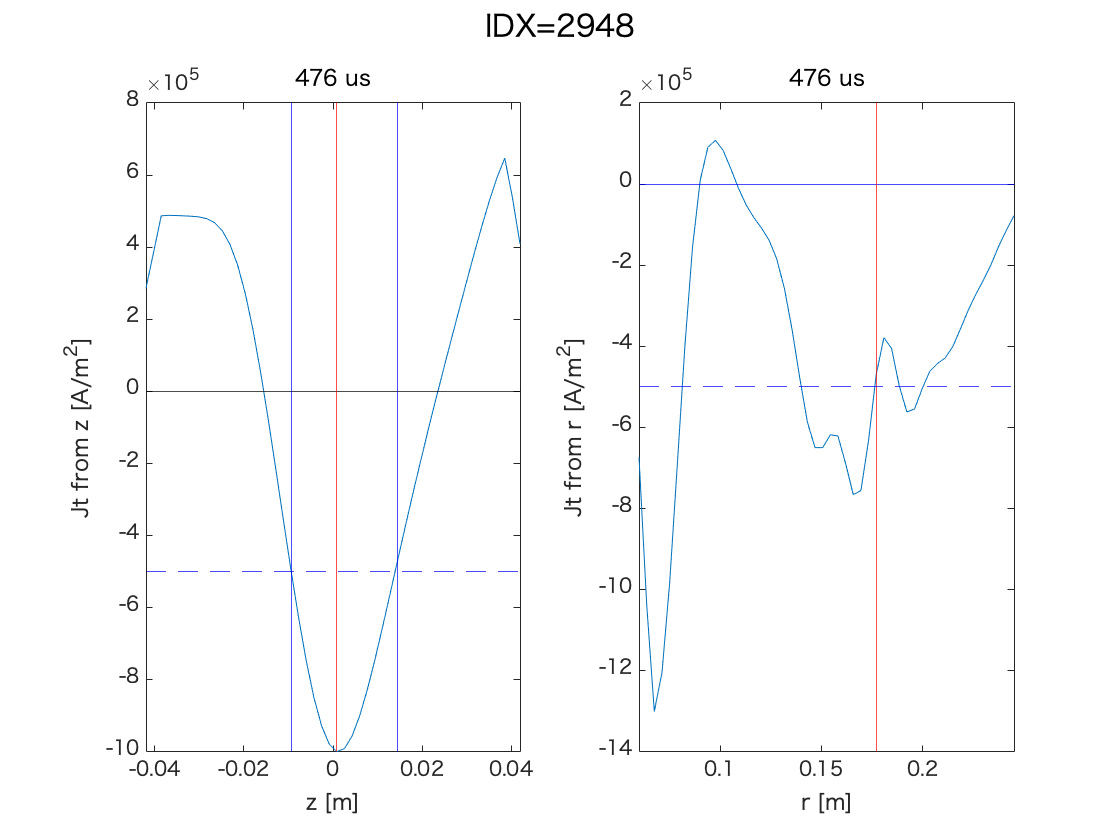

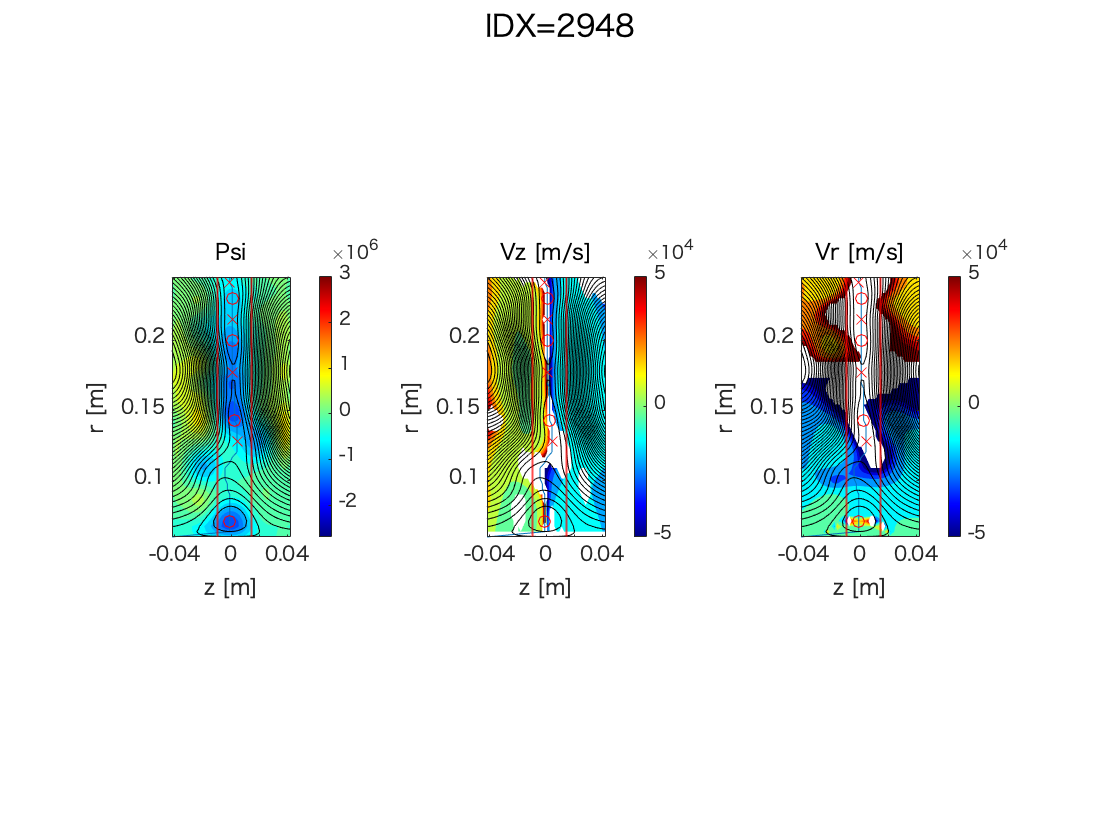

IDX = 2949

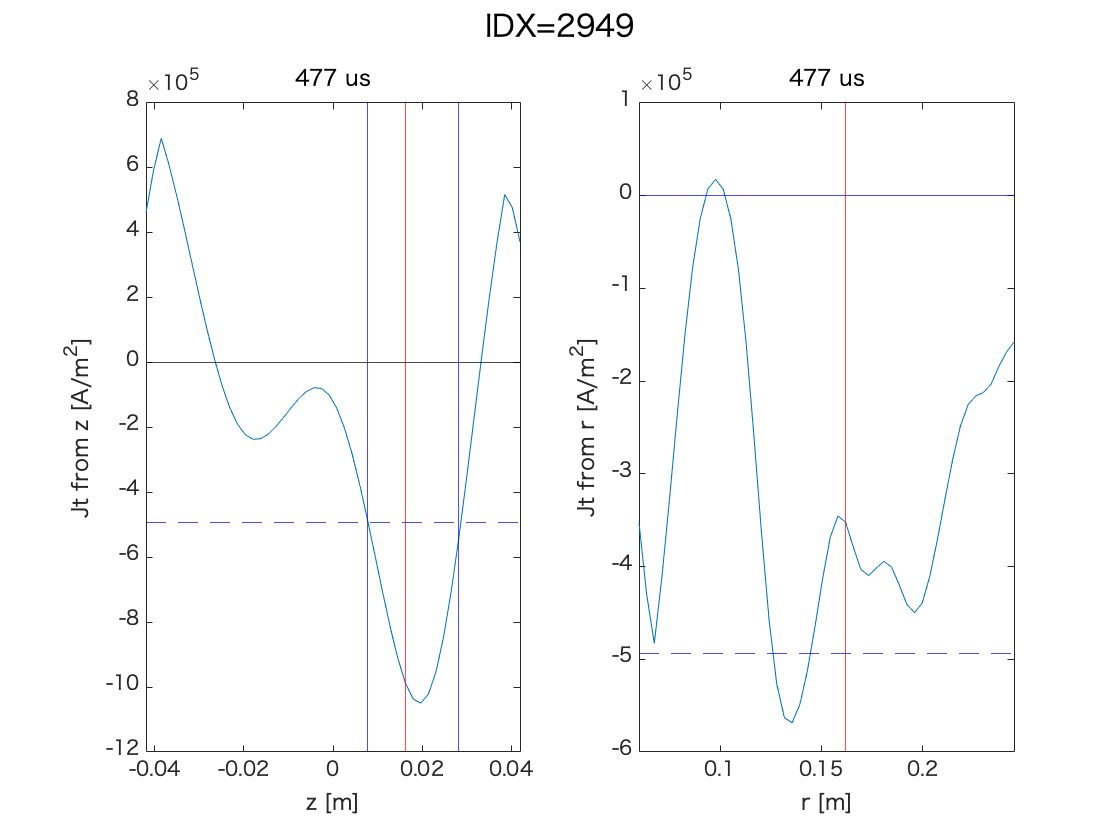

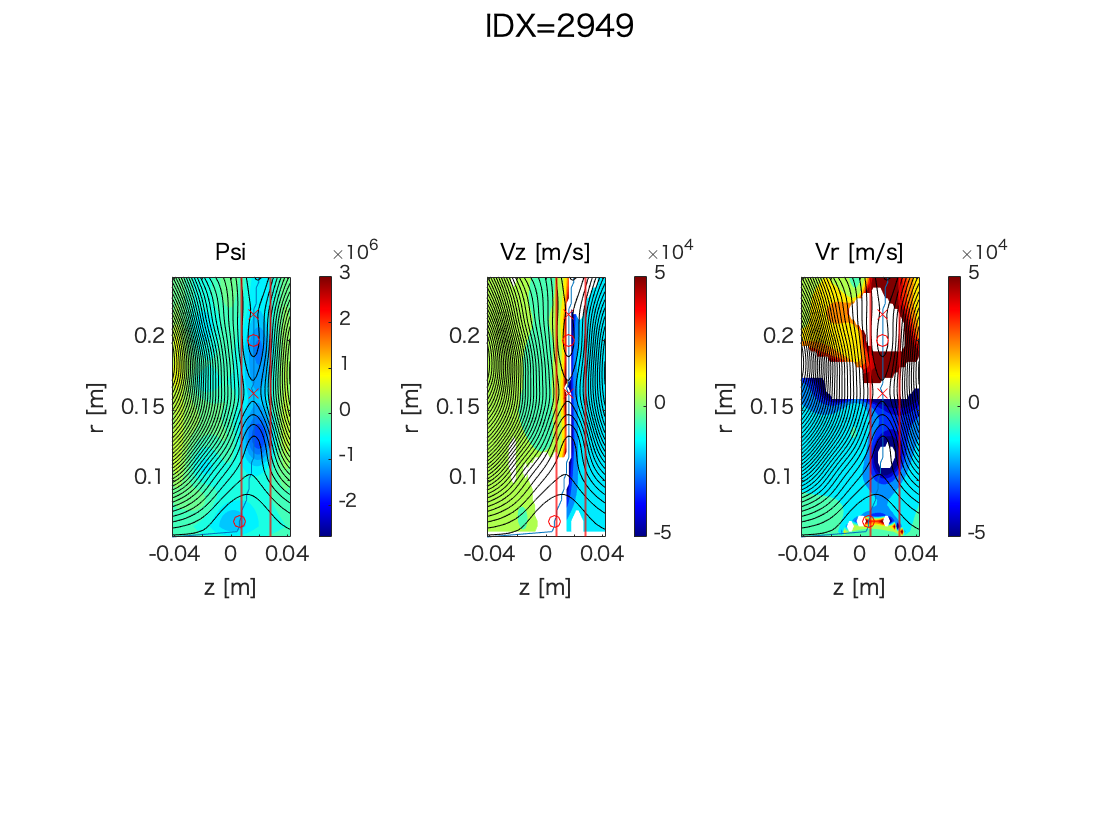

IDX = 2950

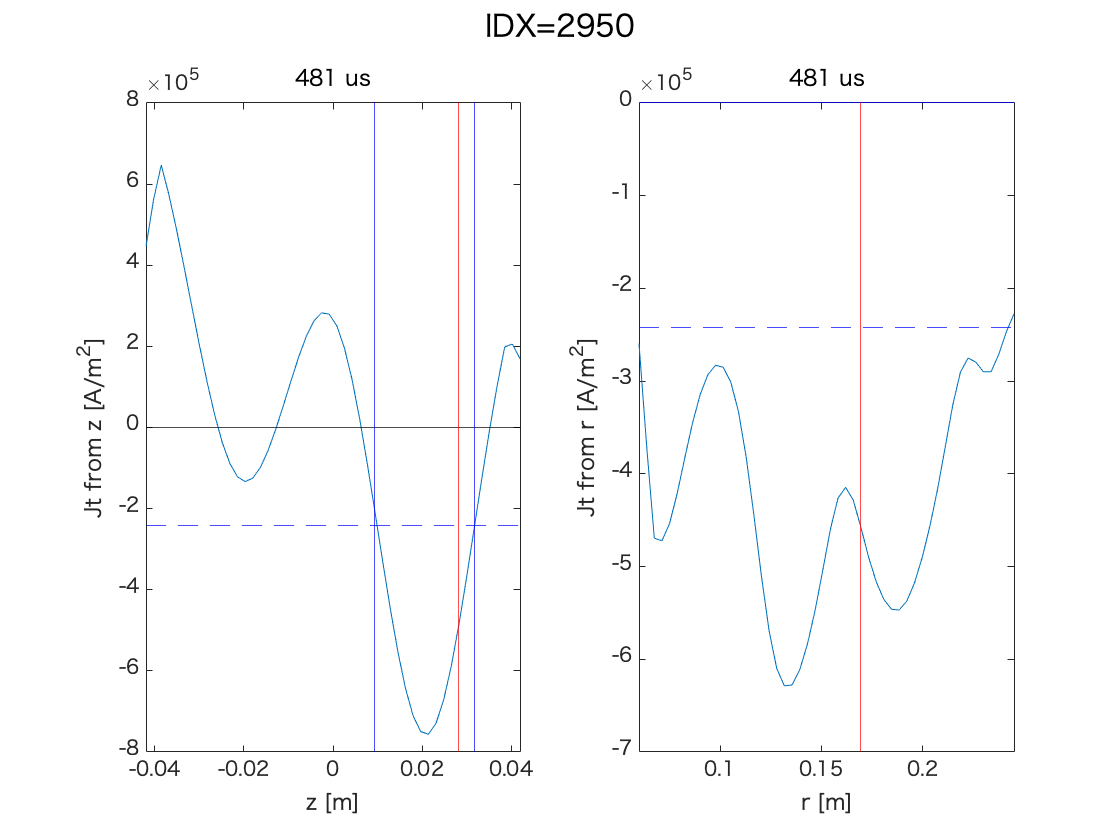

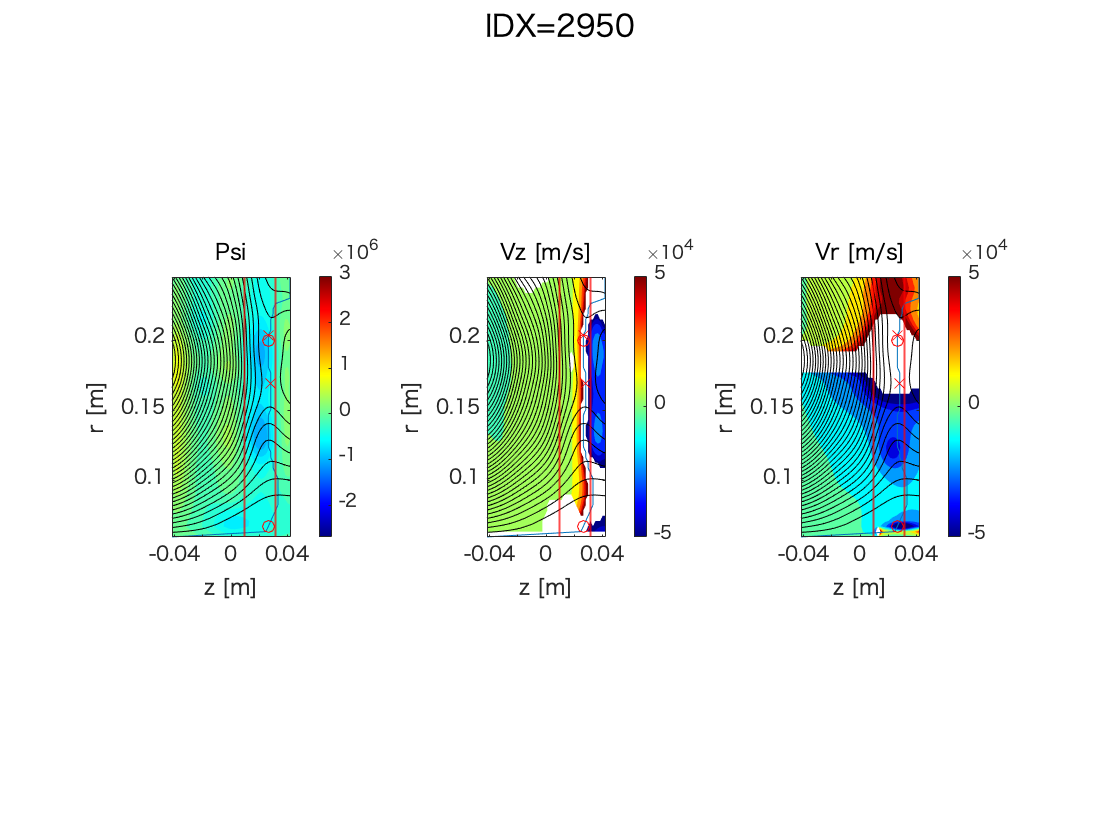

IDX = 2942

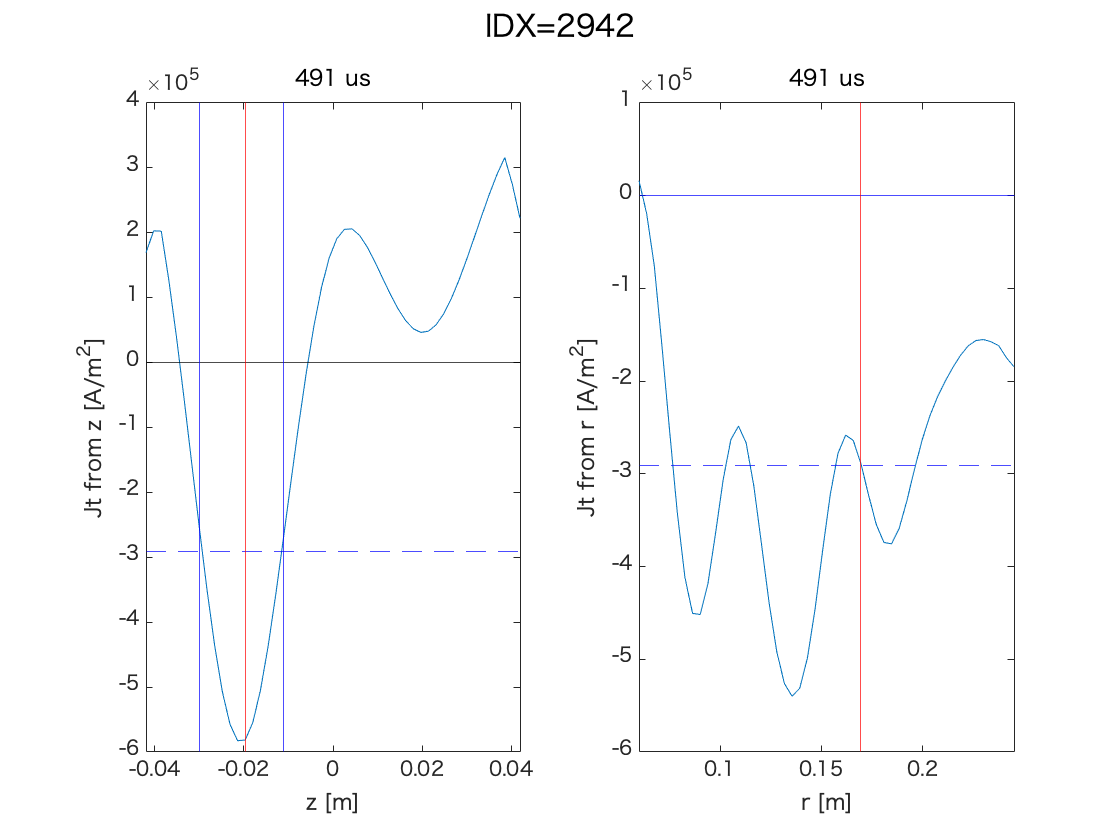

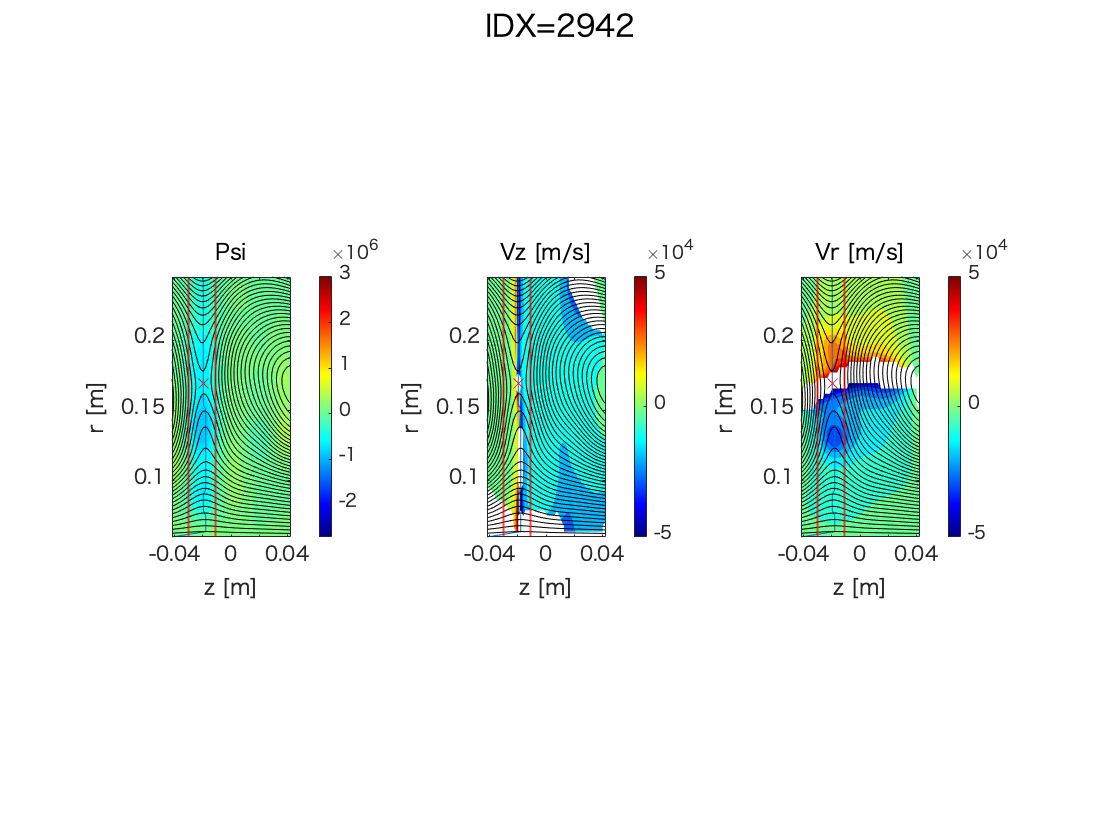

IDX = 2943

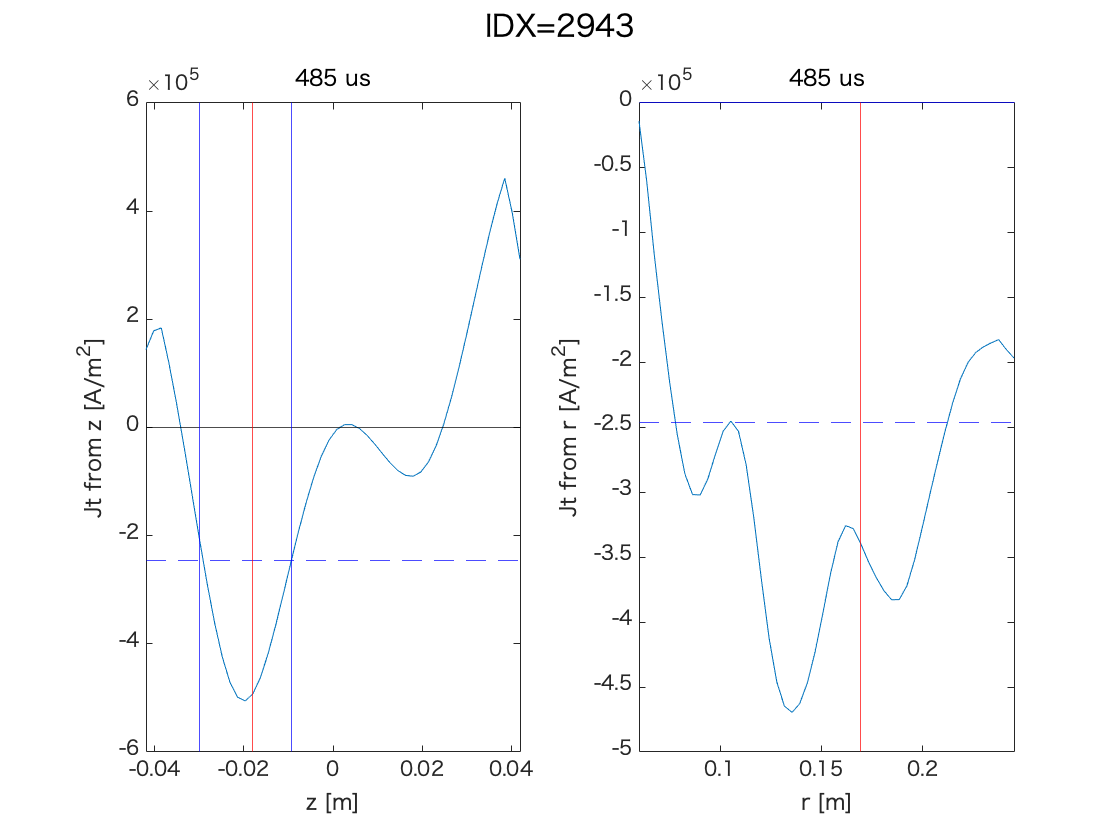

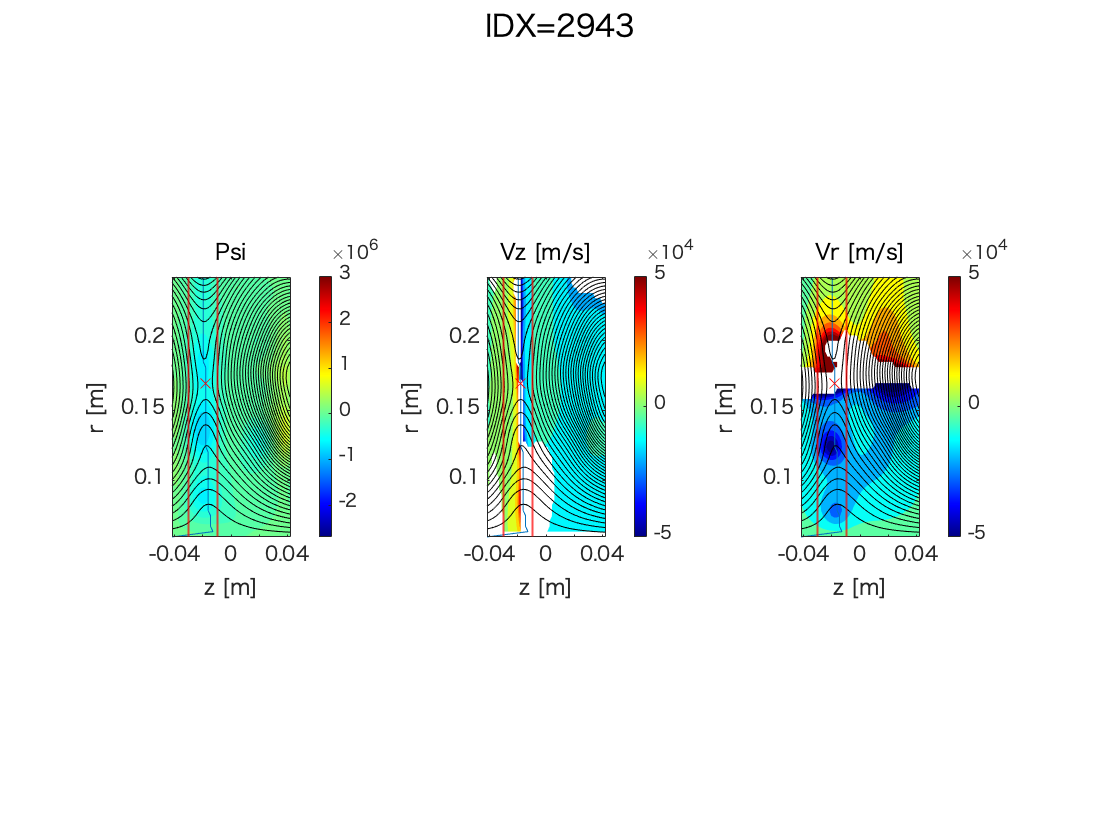

IDX = 2946

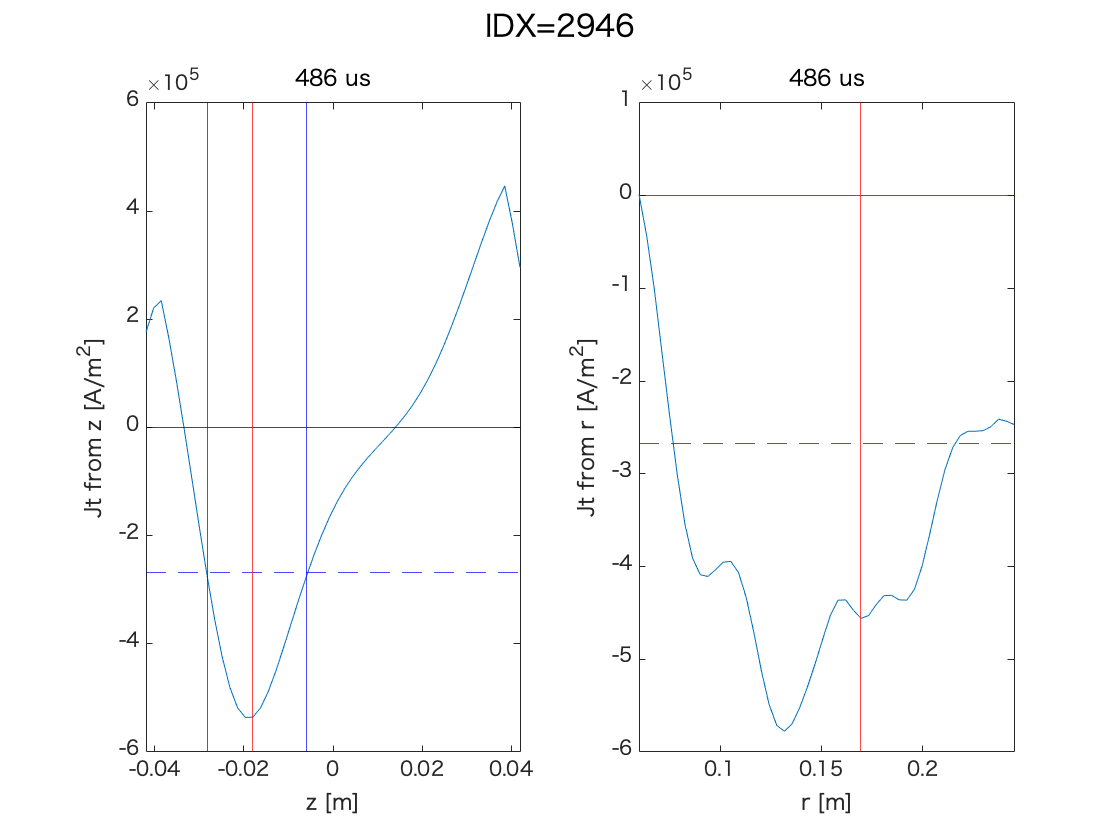

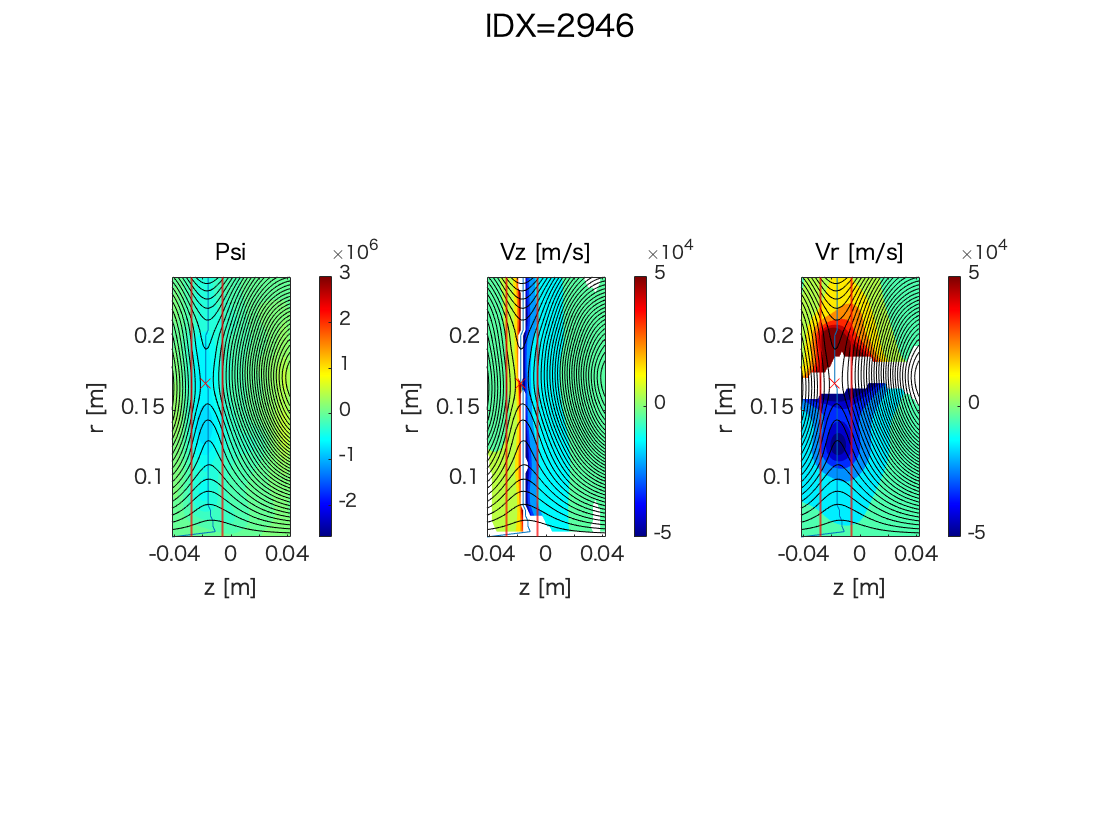

clearvars 
%-except wide xr

%%ファイルへのパスを作る
%それぞれのPCから共有フォルダまでのパスはそれぞれ異なるので各自で設定
pathname.ts3u=getenv('ts3u_path');%old-koalaのts-3uまでのパス
pathname.fourier=getenv('fourier_path');%md0までのpath
pathname.NIFS=getenv('NIFS_path');%resultsまでのpath
pathname.save=getenv('save_path');

DOCID='1wG5fBaiQ7-jOzOI-2pkPAeV6SDiHc_LrOdcbWlvhHBw';
T=getTS6log(DOCID);% ログのテーブルを取得
%  node='Crowbar_us_';  % 検索する列の名前. T.Properties.VariableNamesで一覧表示できる
%  pat=454;   % 検索パターン（数値なら一致検索、文字なら含む検索）　
% 
% subT=searchlog(T,node,pat);% ログのテーブルから当てはまるものを抽出した新しいテーブルを作成


IDXlist=[2911:2913 2925 2926 2927 2931 2933 2947:2950 2942 2943 2946];
% shot=struct('a',2911:2913,'b',[2925 2926 2927],'c',[2931 2933],'d',2947:2950,'e',[2942 2943 2946]);
% IDXlist=shot.a; %【input】テーブルから解析したいshot番号を抽出して入力
%(a)211223/IDX2870:2920(42:44)/2911:2913/dtacq3592:3594
%(b)211224/IDX2922:2950(4,5,8)/2925,2926,2927/dtacq3606,3607,3609
%(c)211224/IDX2922:2950(10,12)/2931,2933/dtacq3611,3613
%(d)211224/IDX2922:2950(26:29)/2947:2950/dtacq3626-3629
%(e)211224/IDX2922:2950(21,22,25)/2942,2943,2946/dtacq3621,3622,3625

tcal=[472 478; 474 479; 474 481; 
    476 484; 476 482; 476 483; 
    485 499; 485 499;
    475 483; 474 483; 473 483; 479 489;
    485 496; 484 494; 483 495]; %15*2

wide=zeros(numel(IDXlist),1); %電流シートの半値幅
xr=zeros(numel(IDXlist),1);
Vzl=zeros(numel(IDXlist),1);
Vzr=zeros(numel(IDXlist),1);

for i=1:numel(IDXlist)
    IDX=IDXlist(i)
    tstart=tcal(i,1);
    tend=tcal(i,2);
    [wide(i),xr(i),Vzl(i),Vzr(i)]=jtsheetcalc(T, IDX, pathname, tstart, tend);
end


%X点でのBt
Bt_xa=45*4e+3*1.256*10^-6/mean(xr(1:3))/2/pi;
Bt_xb=45*4e+3*1.256*10^-6/mean(xr(4:6))/2/pi;
Bt_xc=45*4e+3*1.256*10^-6/mean(xr(7:8))/2/pi;
Bt_xd=45*4e+3*1.256*10^-6/mean(xr(9:12))/2/pi;
Bt_xe=45*4e+3*1.256*10^-6/mean(xr(13:15))/2/pi;

Group=["a";"b";"c";"d";"e"];
Xposition=[mean(xr(1:3));mean(xr(4:6));mean(xr(7:8));mean(xr(9:12));mean(xr(13:15))];
Sheet_width=[mean(wide(1:3));mean(wide(4:6));mean(wide(7:8));mean(wide(9:12));mean(wide(13:15))];
Vz_left=[mean(Vzl(1:3));mean(Vzl(4:6));mean(Vzl(7:8));mean(Vzl(9:12));mean(Vzl(13:15))];
Vz_right=[mean(Vzr(1:3));mean(Vzr(4:6));mean(Vzr(7:8));mean(Vzr(9:12));mean(Vzr(13:15))];
Bt_x=[Bt_xa;Bt_xb;Bt_xc;Bt_xd;Bt_xe];
dataset=table(Group,Xposition,Sheet_width,Vz_left,Vz_right,Bt_x)

dataset = 5×6 table
    Group    Xposition    Sheet_width    Vz_left    Vz_right     Bt_x  
    _____    _________    ___________    _______    ________    _______

     "a"      0.22109      0.026857      9347.2     -6617.2     0.16275
     "b"      0.22109      0.023429      7785.8     -4923.3     0.16275
     "c"       0.2148      0.023143      6358.3     -5611.4     0.16752
     "d"      0.17232      0.021857      4795.1      -10377     0.20881
     "e"      0.16949      0.020571      2463.8     -4857.6     0.21229


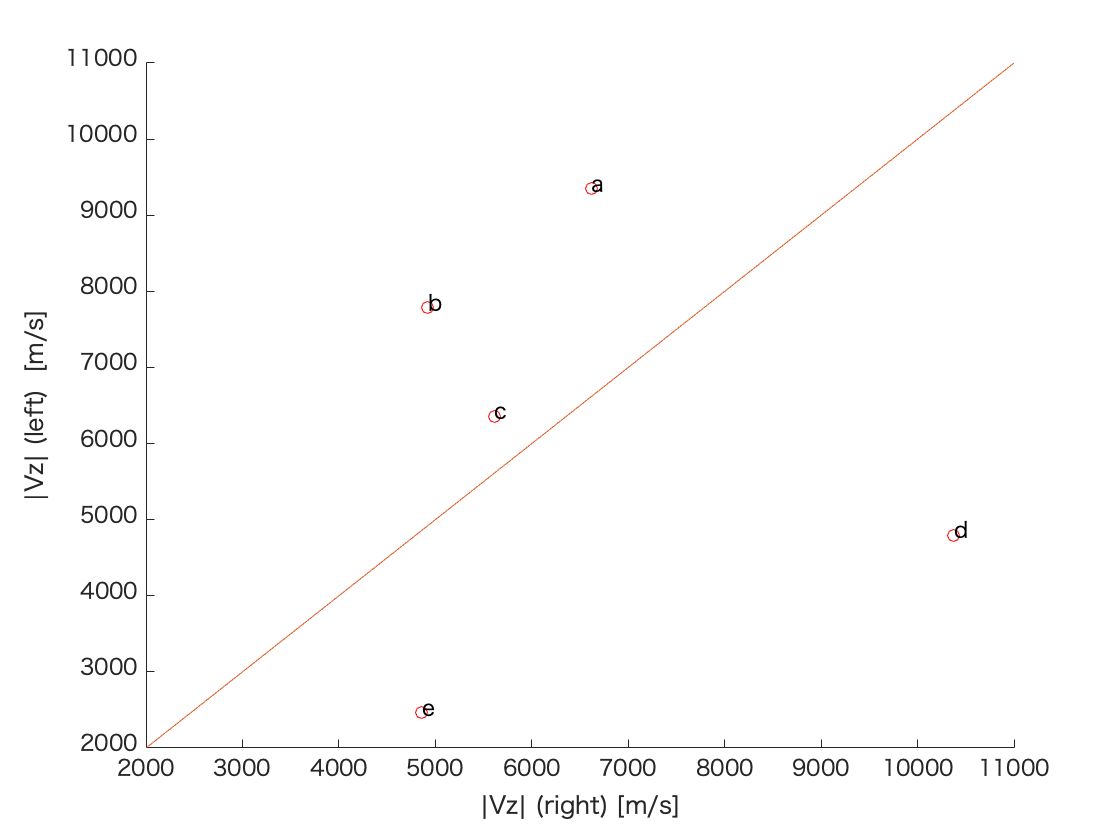


figure
h=scatter(-Vz_right,Vz_left,[],'red');
xlabel('|Vz| (right) [m/s]')
ylabel('|Vz| (left)  [m/s]')
str={'a','b','c','d','e'};
text(-Vz_right,Vz_left,str)
xlim([2e+3 11e+3])
ylim([2e+3 11e+3])
% xとyの表示範囲を取得
x_lim = h.Parent.XLim;
y_lim = h.Parent.YLim;
hold on;
% 対角線の描画
plot(x_lim, y_lim);
% 描画範囲の調節
% xlim(h.Parent.XLim)
% ylim(h.Parent.YLim)
hold off;


% wide_a=mean(wide(1:3))
% wide_b=mean(wide(4:6))
% wide_c=mean(wide(7:8))
% wide_d=mean(wide(9:12))
% wide_e=mean(wide(13:15))
% 
% xr_a=mean(xr(1:3))
% xr_b=mean(xr(4:6))
% xr_c=mean(xr(7:8))
% xr_d=mean(xr(9:12))
% xr_e=mean(xr(13:15))
% 
% Vzl_a=mean(Vzl(1:3))
% Vzl_b=mean(Vzl(4:6))
% Vzl_c=mean(Vzl(7:8))
% Vzl_d=mean(Vzl(9:12))
% Vzl_e=mean(Vzl(13:15))
% 
% Vzr_a=mean(Vzr(1:3))
% Vzr_b=mean(Vzr(4:6))
% Vzr_c=mean(Vzr(7:8))
% Vzr_d=mean(Vzr(9:12))
% Vzr_e=mean(Vzr(13:15))


function [date, shot, TF_shot, offset_TF, i_EF, start, v_TF, d_tacq, d_tacqTF, n] = getinput(T,IDX)
date=T.date(IDX);
shot=T.shot(IDX);
TF_shot=T.TFoffset(IDX);
offset_TF=isfinite(TF_shot);

if isnan(T.EF_A_(IDX))%%NaNでないことを確認（ログが空白だとNaNになる）
    i_EF=150;
else  %NaNなら150をとりあえず代入、記入されているときはその値を使う
    i_EF=T.EF_A_(IDX);
end

start=T.Period_StartTime_(IDX);
v_TF=T.TF_kV_(IDX); %TF[kV]

d_tacq=T.d_tacq(IDX);
d_tacqTF=T.TFdtacq(IDX);

n=50; %rz方向のメッシュ数
end

function [wide,xr,Vzl,Vzr]=jtsheetcalc(T, IDX, pathname, tstart, tend)
trange = tstart:tend+1;
tsize = tend-tstart+1;
column = ceil(sqrt(tsize)); 
row = ceil(tsize/column);

[date, ~, ~, ~, i_EF, ~, ~, d_tacq, d_tacqTF, n] = getinput(T,IDX);%Tのテーブルから入力のリストを出力
[grid2D, data2D] = pcbdata(date, d_tacq, d_tacqTF, trange, [], n,i_EF);

if isstruct(grid2D)==0 %もしdtacqデータがない場合次のloopへ(データがない場合NaNを返しているため)
    return
end

%%%midplaneとかO点、X点を探す
[psimid,mid]=min(data2D.psi,[],2);
[opoint,~]=islocalmin(psimid,1);
[xpoint,~]=islocalmax(psimid,1);
[xp_psi,maxxp]=max(squeeze(psimid),[],1);
r_index=1:n;

% figure
%figure('Position', [0 0 1500 1500],'visible','on');

%%%z方向視線からのJt
Jt_fromz=zeros(tsize,n);
xJt=zeros(tsize,1);
for i=1:tsize
    if sum(maxxp(:,i))>0
        r_maxxp=r_index(maxxp(:,i));
        r_s=max(1,r_maxxp-15);
        r_n=min(n,r_maxxp+15);
        for j=1:n
            Jt_fromz(i,j)=sum(data2D.Jt(r_s:r_n,j,i))/(r_n-r_s+1);            
        end
    end
    %各時刻でのz方向視線からのJtのプロット
%     subplot(row,column,i);
%     plot(grid2D.zq(1,:),Jt_fromz(i,:))
%     yline(0,'b-')
%     xline(grid2D.zq(1,squeeze(mid(maxxp(:,i),:,i))),'r-')
%     ylim([-3e+6 3e+6])
%     title(string(trange(i))+' us')
%     xlabel('z [m]')
%     ylabel('Jt from z [A/m^{2}]')
    
    xJt(i,1)=Jt_fromz(i,squeeze(mid(maxxp(:,i),:,i)));
end

%X点でのJtが最小の時刻
[xJt_min,tmin]=min(xJt);

%半値の交点がぴったり2点の場合に半値幅を求める（交点が2個以外を考慮したverも作りたい）
lind=0;
rind=0;
for j=1:squeeze(mid(maxxp(:,tmin)))
    if (Jt_fromz(tmin,j)-xJt_min*0.5)*(Jt_fromz(tmin,j+1)-xJt_min*0.5)<=0
        if abs(Jt_fromz(tmin,j)-xJt_min*0.5)<abs(Jt_fromz(tmin,j+1)-xJt_min*0.5)
            lind=j;
            sheet_left=grid2D.zq(1,j);
        else
            lind=j+1;
            sheet_left=grid2D.zq(1,j+1);
        end  
    end
end

for j=squeeze(mid(maxxp(:,tmin))):n-1
    if (Jt_fromz(tmin,j)-xJt_min*0.5)*(Jt_fromz(tmin,j+1)-xJt_min*0.5)<=0
        if abs(Jt_fromz(tmin,j)-xJt_min*0.5)<abs(Jt_fromz(tmin,j+1)-xJt_min*0.5)
            rind=j;
            sheet_right=grid2D.zq(1,j);
        else
            rind=j+1;
            sheet_right=grid2D.zq(1,j+1);
        end  
    end
end

%[[output]]
wide=sheet_right-sheet_left;
xr=grid2D.rq(maxxp(:,tmin),1);
%x_z=grid2D.zq(1,squeeze(mid(maxxp(:,tmin)

%X点でのJtのプロット
% figure
% plot(tstart:tend, xJt)
% xlabel('Time [us]')
% ylabel('Jt at Xpoint[A/m^{2}]')

%電流シート高さLの定義
Jt_fromr=zeros(n,1);
for j=1:n
    Jt_fromr(j,1)=sum(data2D.Jt(j,lind:rind))/(rind-lind+1);            
end
%xJt_r=Jt_fromr(r_maxxp,1);

%速度Vの各成分を計算
% Vz=zeros(size(grid2D.rq,1),size(grid2D.rq,2));
% Vr=zeros(size(grid2D.rq,1),size(grid2D.rq,2));
Vz(:,:)=data2D.Et(:,:,tmin)./data2D.Br(:,:,tmin);
Vr(:,:)=-data2D.Et(:,:,tmin)./data2D.Bz(:,:,tmin);
%vが大きすぎるところを外れ値検索で外す
vzind=isoutlier(Vz,'median',1);
Vz(vzind)=NaN;
vrind=isoutlier(Vr,'median',1);
Vr(vrind)=NaN;
clear vzind vrind
Vz(abs(Vz) > 10*1e+4) = NaN;
Vr(abs(Vr) > 10*1e+4) = NaN;

%%%z方向視線からのVz
%NaNが含まれる場合は対応していない
L_s=max(1,r_maxxp-5);
L_n=min(n,r_maxxp+5);
%[[output]]
Vzl=sum(Vz(L_s:L_n,lind-5:lind-1),'all')/(5*(L_n-L_s+1));
Vzr=sum(Vz(L_s:L_n,rind+1:rind+5),'all')/(5*(L_n-L_s+1));
%Vz(L_s:L_n,rind+1:rind+5)


%plot

% %X点でのJtが最小の時刻でのz方向視線からのJtのプロット
% figure('Position', [0 0 1000 500],'visible','on');
figure
subplot(1,2,1)
plot(grid2D.zq(1,:),Jt_fromz(tmin,:))
xlim([grid2D.zq(1,1) grid2D.zq(1,n)])
yline(0,'k-')
yline(xJt_min*0.5,'b--') %半値幅
xline(grid2D.zq(1,squeeze(mid(maxxp(:,tmin),:,tmin))),'r-')
xline(sheet_left,'b-')
xline(sheet_right,'b-')
title(string(trange(tmin))+' us')
xlabel('z [m]')
ylabel('Jt from z [A/m^{2}]')

%tminでのr方向視線からのJtのプロット
%figure
subplot(1,2,2)
plot(grid2D.rq(:,1),Jt_fromr)
xlim([grid2D.rq(1,1) grid2D.rq(n,1)])
yline(0,'k-')
xline(xr,'r-')
% yline(xJt_r*0.5,'b--') %r方向視線での半値幅
yline(xJt_min*0.5,'b--') %z方向視線での半値幅
title(string(trange(tmin))+' us')
xlabel('r [m]')
ylabel('Jt from r [A/m^{2}]')

sgtitle(strcat('IDX=',num2str(IDX)))

% saveas(gcf,strcat(pathname.save,'\IDX',num2str(IDX),'Jtplot.png'))
% close
   
%磁気面のプロット
%figure('Position', [0 0 1000 500],'visible','on');
figure
%f=figure;
%f.WindowState = 'maximized';
subplot(1,3,1)
contourf(grid2D.zq(1,:),grid2D.rq(:,1),data2D.Jt(:,:,tmin),10,'LineStyle','none')
colormap(jet)
axis image
axis tight manual
caxis([-2.7*1e+6,3*1e+6]) %カラーバーの軸の範囲
%caxis([-maxrange,maxrange])
colorbar('Location','eastoutside')
hold on
plot(grid2D.zq(1,squeeze(mid(:,:,tmin))),grid2D.rq(:,1))
contour(grid2D.zq(1,:),grid2D.rq(:,1),squeeze(data2D.psi(:,:,tmin)),35,'black')
plot(grid2D.zq(1,squeeze(mid(opoint(:,:,tmin),:,tmin))),grid2D.rq(opoint(:,:,tmin),1),"ro")
plot(grid2D.zq(1,squeeze(mid(xpoint(:,:,tmin),:,tmin))),grid2D.rq(xpoint(:,:,tmin),1),"rx")
xline(sheet_left,'r-','LineWidth',1)
xline(sheet_right,'r-','LineWidth',1)
hold off
title('Psi')
xlabel('z [m]')
ylabel('r [m]')

subplot(1,3,2)
contourf(grid2D.zq(1,:),grid2D.rq(:,1),Vz(:,:),20,'LineStyle','none')
colormap(jet)
axis image
axis tight manual
caxis([-5*1e+4,5*1e+4])
colorbar('Location','eastoutside')
hold on
plot(grid2D.zq(1,squeeze(mid(:,:,tmin))),grid2D.rq(:,1))
contour(grid2D.zq(1,:),grid2D.rq(:,1),squeeze(data2D.psi(:,:,tmin)),35,'black')
plot(grid2D.zq(1,squeeze(mid(opoint(:,:,tmin),:,tmin))),grid2D.rq(opoint(:,:,tmin),1),"ro")
plot(grid2D.zq(1,squeeze(mid(xpoint(:,:,tmin),:,tmin))),grid2D.rq(xpoint(:,:,tmin),1),"rx")
xline(sheet_left,'r-','LineWidth',1)
xline(sheet_right,'r-','LineWidth',1)
hold off
title('Vz [m/s]')
xlabel('z [m]')
ylabel('r [m]')

subplot(1,3,3)
contourf(grid2D.zq(1,:),grid2D.rq(:,1),Vr(:,:),20,'LineStyle','none')
colormap(jet)
axis image
axis tight manual
caxis([-5*1e+4,5*1e+4])
colorbar('Location','eastoutside')
hold on
plot(grid2D.zq(1,squeeze(mid(:,:,tmin))),grid2D.rq(:,1))
contour(grid2D.zq(1,:),grid2D.rq(:,1),squeeze(data2D.psi(:,:,tmin)),35,'black')
plot(grid2D.zq(1,squeeze(mid(opoint(:,:,tmin),:,tmin))),grid2D.rq(opoint(:,:,tmin),1),"ro")
plot(grid2D.zq(1,squeeze(mid(xpoint(:,:,tmin),:,tmin))),grid2D.rq(xpoint(:,:,tmin),1),"rx")
xline(sheet_left,'r-','LineWidth',1)
xline(sheet_right,'r-','LineWidth',1)
hold off
title('Vr [m/s]')
xlabel('z [m]')
ylabel('r [m]')

sgtitle(strcat('IDX=',num2str(IDX)))

% saveas(gcf,strcat(pathname.save,'\IDX',num2str(IDX),'vplot.png'))
% close

end
